## **Name : Thanawath Huayhongthong**

## Student ID : 6388016

## Section : 1

# **Triangulation Matting Project **

Read all 4 images

bg1 = imread('bg1.png')

bg1 = 720×876×3 uint8 array
bg1(:,:,1) =

   144   145   141   143   143   145   144   144   142   141   142   142   145   141   138   141   143   145   142   142   140   140   139   142   143   139   139   138   140   142   144   143   141   143   138   137   142   144   141   142   140   137   137   142   140   140   142   143   145   147   144   139   137   141   141   142   141   139   140   138   139   143   139   140   140   134   135   142   145   140   142   143   139   139   143   145   144   140   139   136   139   141   141   139   141   143   142   138   139   137   136   146   142   139   142   143   144   145   140   145   145   138   139   139   138   139   147   147   147   144   139   145   143   144   143   141   142   143   144   143   144   143   136   138   142   142   142   140   140   145   145   141   142   148   143   144   145   141   143   144   140   142   141   144   142   141   143   146   144   144   144   143   144   143   143   144   141   140   142   1

bg2 = imread('bg2.png')

bg2 = 720×876×3 uint8 array
bg2(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

fg1 = imread('fg1.png')

fg1 = 720×876×3 uint8 array
fg1(:,:,1) =

   144   145   141   143   143   145   144   144   142   141   142   142   145   141   138   141   143   145   142   142   140   140   139   142   143   139   139   138   140   142   144   143   141   143   138   137   142   144   141   142   140   137   137   142   140   140   142   143   145   147   144   139   137   141   141   142   141   139   140   138   139   143   139   140   140   134   135   142   145   140   142   143   139   139   143   145   144   140   139   136   139   141   141   139   141   143   142   138   139   137   136   146   142   139   142   143   144   145   140   145   145   138   139   139   138   139   147   147   147   144   139   145   143   144   143   141   142   143   144   143   144   143   136   138   142   142   142   140   140   145   145   141   142   148   143   144   145   141   143   144   140   142   141   144   142   141   143   146   144   144   144   143   144   143   143   144   141   140   142   1

fg2 = imread('fg2.png')

fg2 = 720×876×3 uint8 array
fg2(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

Display all 4 images

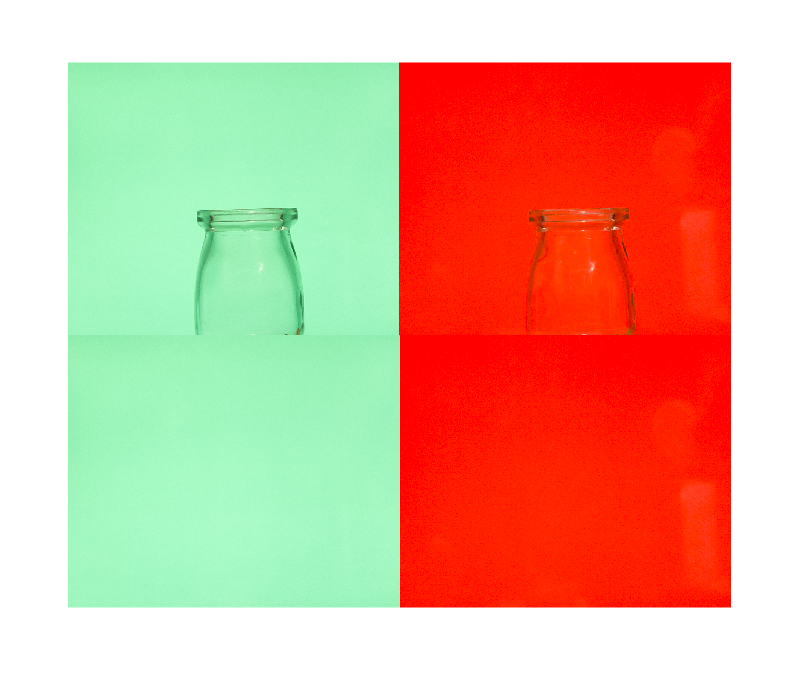

%imshow(fg1);
%imshow(fg2);
%imshow(bg1);
%imshow(bg2);
%imshowpair(fg1,fg2,'montage')
%imshowpair(bg1,bg2,'montage')
montage({fg1,fg2,bg1,bg2})

Convert to double

Br1 = bg1(:,:,1);
Bg1 = bg1(:,:,2);
Bb1 = bg1(:,:,3);
Br2 = bg2(:,:,1);
Bg2 = bg2(:,:,2);
Bb2 = bg2(:,:,3);
Cr1 = fg1(:,:,1);
Cg1 = fg1(:,:,2);
Cb1 = fg1(:,:,3);
Cr2 = fg2(:,:,1);
Cg2 = fg2(:,:,2);
Cb2 = fg2(:,:,3);
Br1 = im2double(Br1);
Bg1 = im2double(Bg1);
Bb1 = im2double(Bb1);
Br2 = im2double(Br2);
Bg2 = im2double(Bg2);
Bb2 = im2double(Bb2);
Cr1 = im2double(Cr1);
Cg1 = im2double(Cg1);
Cb1 = im2double(Cb1);
Cr2 = im2double(Cr2);
Cg2 = im2double(Cg2);
Cb2 = im2double(Cb2);

Compute alpha

up = (((Cr1-Cr2).*(Br1-Br2)) + ((Cg1-Cg2).*(Bg1-Bg2)) + ((Cb1-Cb2).*(Bb1-Bb2)));
down = (((Br1-Br2).^2) + ((Bg1-Bg2).^2) + ((Bb1-Bb2).^2));
alpha = 1 - (up./down);

Compute foreground colors of object from background 1 

Fr1 = (Cr1-(1-alpha).*Br1)./alpha;
Fr1(isnan(Fr1)) = 0;
Fr1 = im2gray(Fr1);
Fg1 = (Cg1-(1-alpha).*Bg1)./alpha;
Fg1(isnan(Fg1)) = 0;
Fg1 = im2gray(Fg1);
Fb1 = (Cb1-(1-alpha).*Bb1)./alpha;
Fb1(isnan(Fb1)) = 0;
Fb1 = im2gray(Fb1);
Fore1 = cat(3,Fr1,Fg1,Fb1);

Compute foreground colors of object from background 2

Fr2 = (Cr2-(1-alpha).*Br2)./alpha;
Fr2(isnan(Fr2)) = 0;
Fr2 = im2gray(Fr2);
Fg2 = (Cg2-(1-alpha).*Bg2)./alpha;
Fg2(isnan(Fg2)) = 0;
Fg2 = im2gray(Fg2);
Fb2 = (Cb2-(1-alpha).*Bb2)./alpha;
Fb2(isnan(Fb2)) = 0;
Fb2 = im2gray(Fb2);
Fore2 = cat(3,Fr2,Fg2,Fb2);

Display the extracted foreground object / matte from background 1 and 2

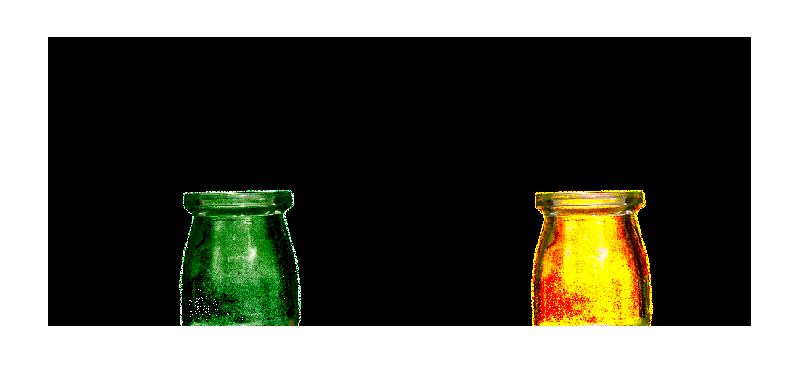

%imshow(Fore1)
%imshow(Fore2)
montage({Fore1,Fore2});

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

whitebg = (Br1 .* 0)+1;
CompositeWhite_r1 = alpha .* Fr1 + (1 - alpha) .* whitebg;
CompositeWhite_g1 = alpha .* Fg1 + (1 - alpha) .* whitebg;
CompositeWhite_b1 = alpha .* Fb1 + (1 - alpha) .* whitebg;
CompositeWhite_r2 = alpha .* Fr2 + (1 - alpha) .* whitebg;
CompositeWhite_g2 = alpha .* Fg2 + (1 - alpha) .* whitebg;
CompositeWhite_b2 = alpha .* Fb2 + (1 - alpha) .* whitebg;
com_wh1 = cat(3,CompositeWhite_r1 , CompositeWhite_g1, CompositeWhite_b1);
com_wh2 = cat(3,CompositeWhite_r2 , CompositeWhite_g2, CompositeWhite_b2);

Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

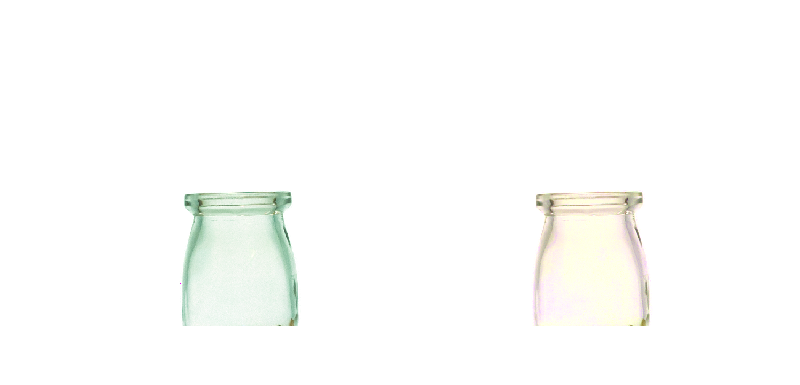

%imshow(fi1);
%imshow(fi2);
montage({com_wh1,com_wh2});

Read new background image to do the composition and display it.

new_bg = imread("new_bg1.png");

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

new_bg_r = new_bg(:,:,1);
new_bg_g = new_bg(:,:,2);
new_bg_b = new_bg(:,:,3);
new_bg_r = im2double(new_bg_r);
new_bg_g = im2double(new_bg_g);
new_bg_b = im2double(new_bg_b);
newCr1 = alpha .* Fr1 + (1 - alpha) .* new_bg_r;
newCg1 = alpha .* Fg1 + (1 - alpha) .* new_bg_g;
newCb1 = alpha .* Fb1 + (1 - alpha) .* new_bg_b;
newCr2 = alpha .* Fr2 + (1 - alpha) .* new_bg_r;
newCg2 = alpha .* Fg2 + (1 - alpha) .* new_bg_g;
newCb2 = alpha .* Fb2 + (1 - alpha) .* new_bg_b;
NewCom1 = cat(3, newCr1, newCg1, newCb1);
NewCom2 = cat(3, newCr2, newCg2, newCb2);

Display the composition of extracted foreground object from background 1 and 2 with the new background image

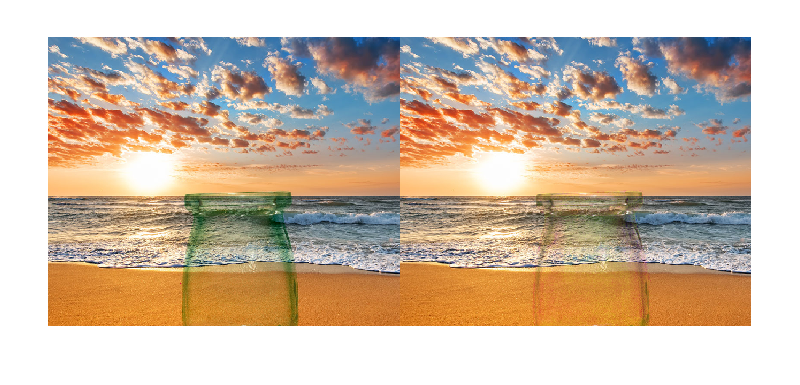

%imshow(NewCom1);
%imshow(Newcom2);
montage({NewCom1,NewCom2});